# Model Based Systems Engineering for Space-Based Applications

This project demostrates how to model a space mission architecture in Simulink with System Composer™ and Aerospace Blockset™ for a 1U CubeSat in low Earth orbit (LEO). The CubeSat's mission is to image MathWorks Headquarters in Natick, Massachusetts at least once per day.  The project references the Aerospace Blockset *CubeSat Simulation* *Project*, reusing the vehicle dynamics, environment models, data dictionaries, and flight control system models defined in that project.

This project demonstrates how to:

- Define system level requirements for a CubeSat mission in Simulink®

- Compose a system architecture for the mission in System Composer

- Link system-level requirements to components in the architecture

- Model vehicle dynamics and flight control systems with Aerospace Blockset

- Validate orbital requirements using mission analysis tools and Simulink Test™

## Define System-level Requirements

Define a set of system-level requirements for the mission.  You can import these requirements from third-party requirement management tools as ReqIF (Requirements Interchange Format) files or author them directly in the Simulink Requirements Editor.

This example contains a set of system-level requirements stored in *SystemRequirements.slreqx*. Open this requirement specification file in the Simulink** Requirements Editor**. Access the **Requirements Editor** from the **Apps** tab, or by double-clicking on *SystemRequirements.slreqx* in the project folder browser*.*

Our top level requirement for this mission is:

- The system shall provide and store visual imagery of MathWorks headquarters [42.2775 N, 71.2468 W] once daily at 10 meters resolution.

Additional requirements are decomposed from this top-level requirement to create a hierarchy of requirements for the architecture.

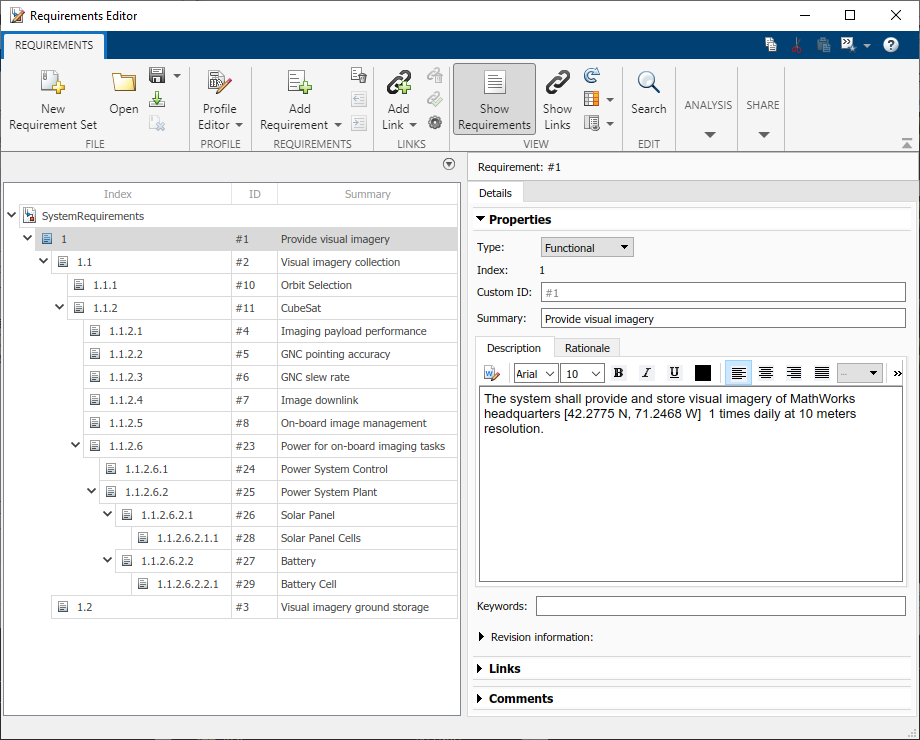

## Compose a System Architecture

System Composer enables the specification and analysis of architectures for model-based systems engineering. Use the system-level requirements defined above to guide the creation of an architecture model in System Composer. The architecture in this example is based on *CubeSat Reference Model (CRM)* developed by the International Council on Systems Engineering (INCOSE) Space Systems Working Group (SSWG) [1].

arch.model = "asbCubeSatArchModel";
open_system(arch.model);

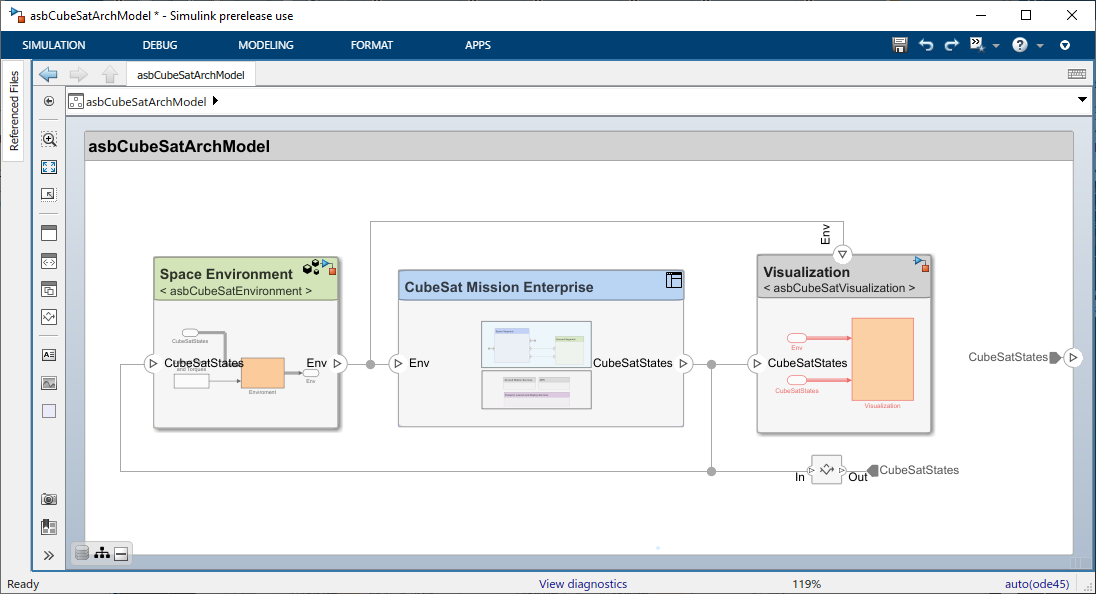

The architecture is composed of components, ports, and connectors. A component is a part of a system that fulfills a clear function in the context of the architecture. It defines an architecture element, such as a system, a subsystem, hardware, software, or other conceptual entity. 

Ports are nodes on a component or architecture that represents a point of interaction with its environment. A port permits the flow of information to and from other components or systems.  Connectors are lines that provide connections between ports. Connectors describe how information flows between components in an architecture.

## Extend the Architecture with Stereotypes and Interfaces

You can add additional level of detail to an architecture using stereotypes and interfaces. 

### Stereotypes

Stereotypes provide a mechanism to extend the architecture elements by adding domain-specific metadata to the element.  Stereotypes are applied to components, connectors, ports, and other architecture elements to provide these elements with a common set of properties such as mass, cost, power, etc.  

Packages of stereotypes used by one or more architectures are stored in Profiles.  This example includes a profile of stereotypes called *CubeSatProfile.xml*.  To view, edit, or add new stereotypes to the profile, open this profile in the **Profile Editor** from the **Modeling** Tab.

This profile defines a set of stereotypes that are applied to components and connectors in the CubeSat architecture.

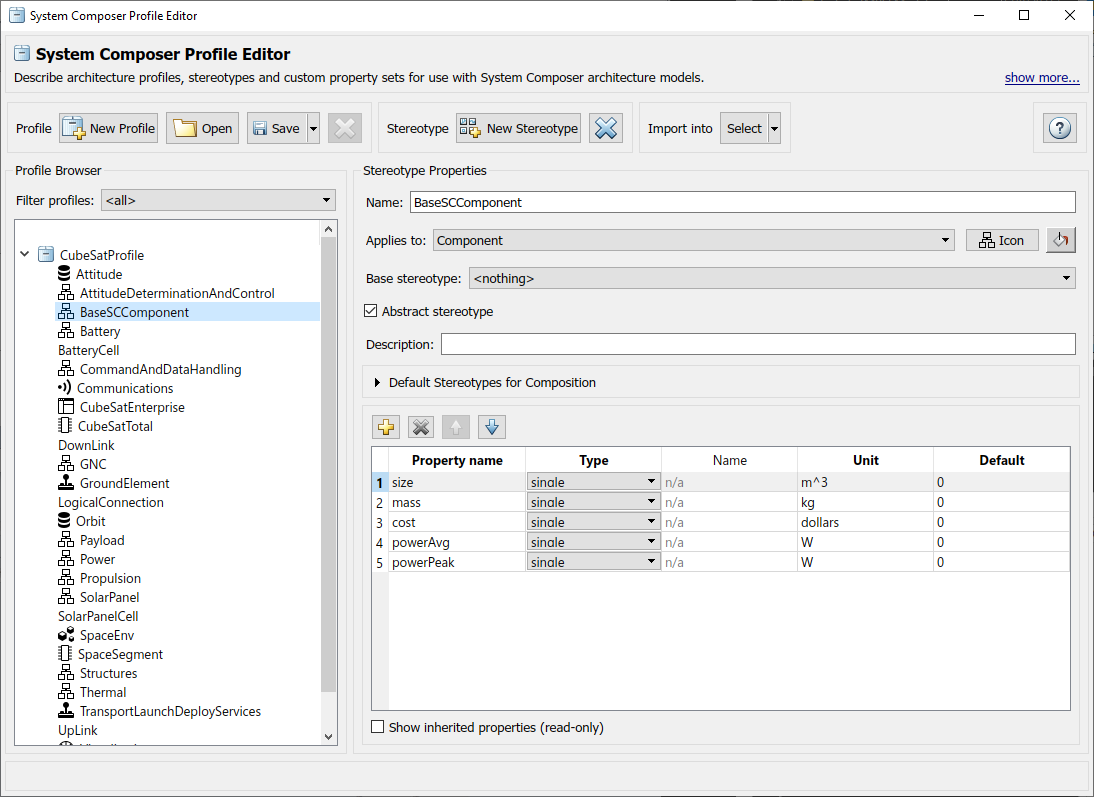

Stereotypes can also inherit properties from abstract base stereotypes. For example, `BaseSCComponent` in the profile above contains properties for size, mass, cost, and power demand.  We can add another stereotype to the profile, `CubeSatTotal`, and define `BaseSCComponent` as its base stereotype.  `CubeSatTotal` adds in it's own property, nominalVoltage, but also inherits properties from its base stereotype.

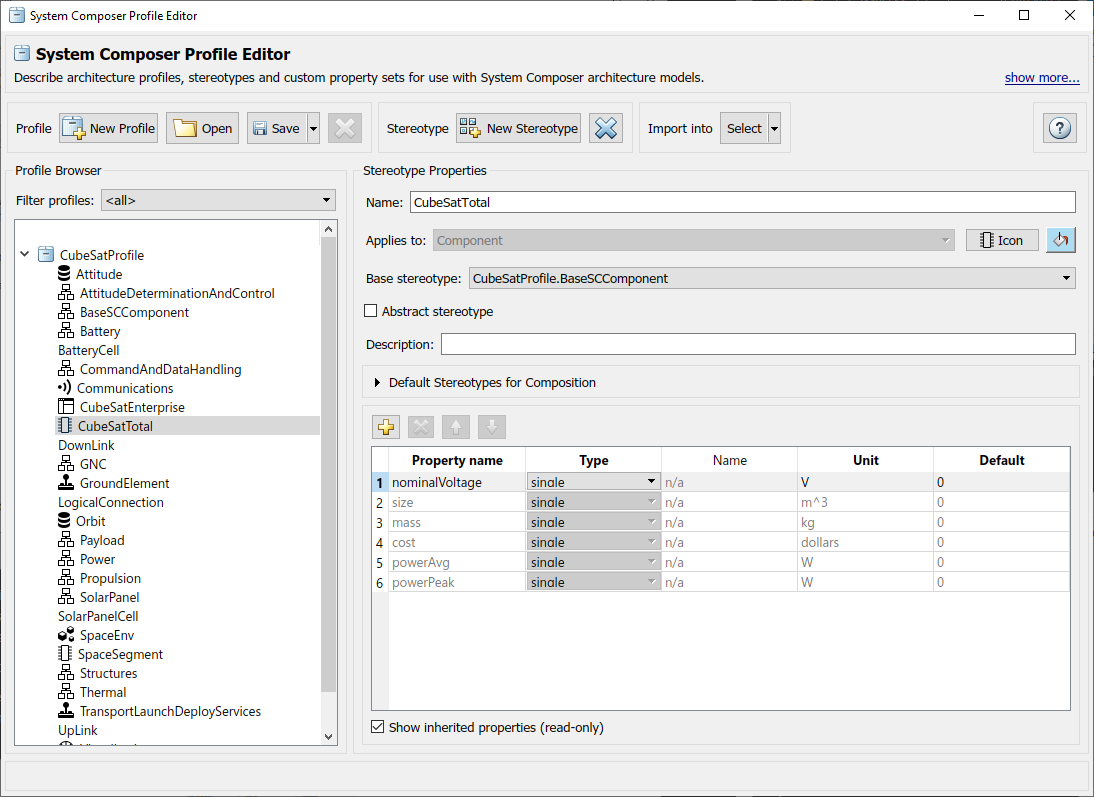

In the architecture model, apply the `CubeSatTotal` stereotype to CubeSat system component (`asbCubeSatArchModel/CubeSat Mission Enterprise/Space Segment/CubeSat`). Select the component in the model.  In the Property Inspector, select the desired stereotype from the drop-down window.  Next set property values for the CubeSat component.

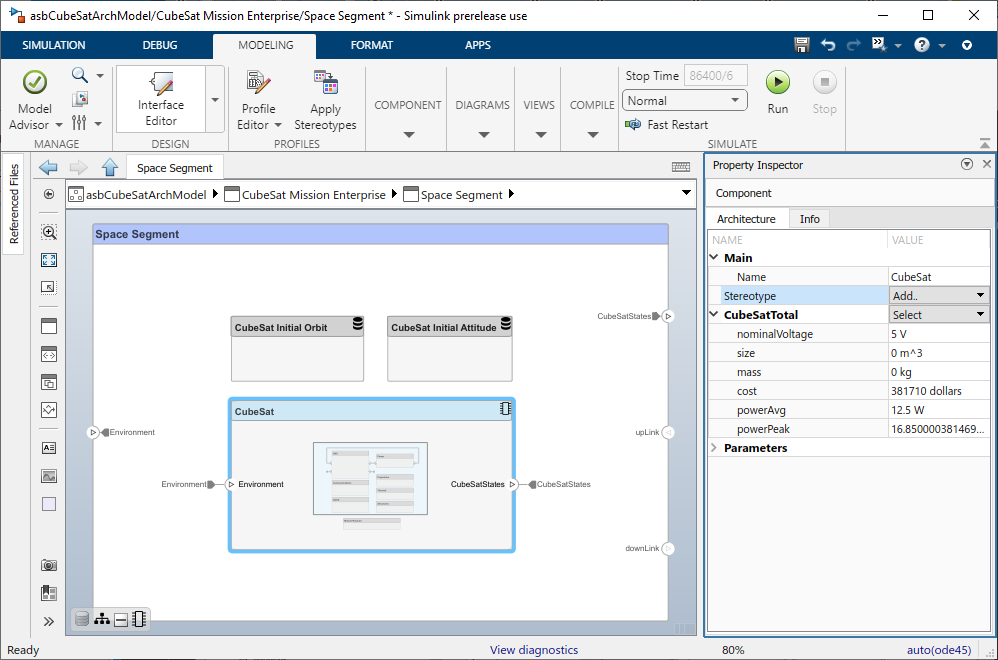

### Interfaces

Data interfaces define the kind of information that flows through a port. The same interface can be assigned to multiple ports. A data interface can be composite, meaning that it can include data elements that describe the properties of an interface signal. Create and manage interfaces from the **Interface Editor**. Existing users of Simulink may draw a parallel between interfaces in System Composer and busses in Simulink. In fact, busses can be used to define interfaces (and vice versa). For example, the data dictionary* asbCubeSatModelData.sldd* contains several bus definitions, including `ACSOutBus`, that can be viewed in the **Interface Editor** and applied to architecture ports.

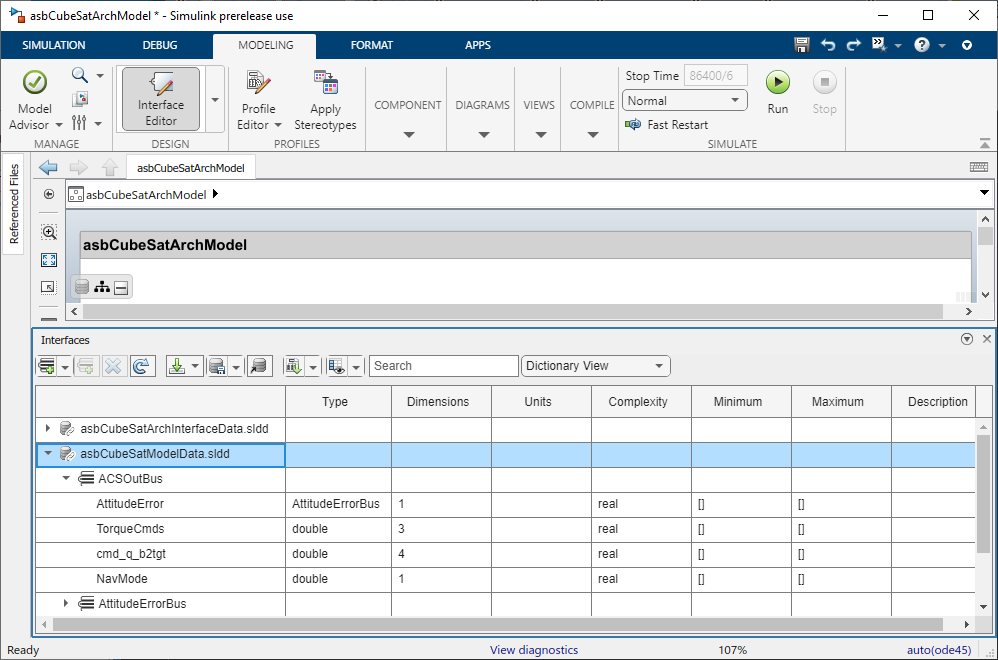

## Visualize the System with Architecture Views

Now that we have implemented our architecture using components, stereotypes, ports, and interfaces, we can visualize our system with an Architecture view.  In the **Modeling** Tab, select **Views**. 

Use the **Component Heirarchy** view to show our system component heirarchy.  Each component also lists its stereotype property values and ports.

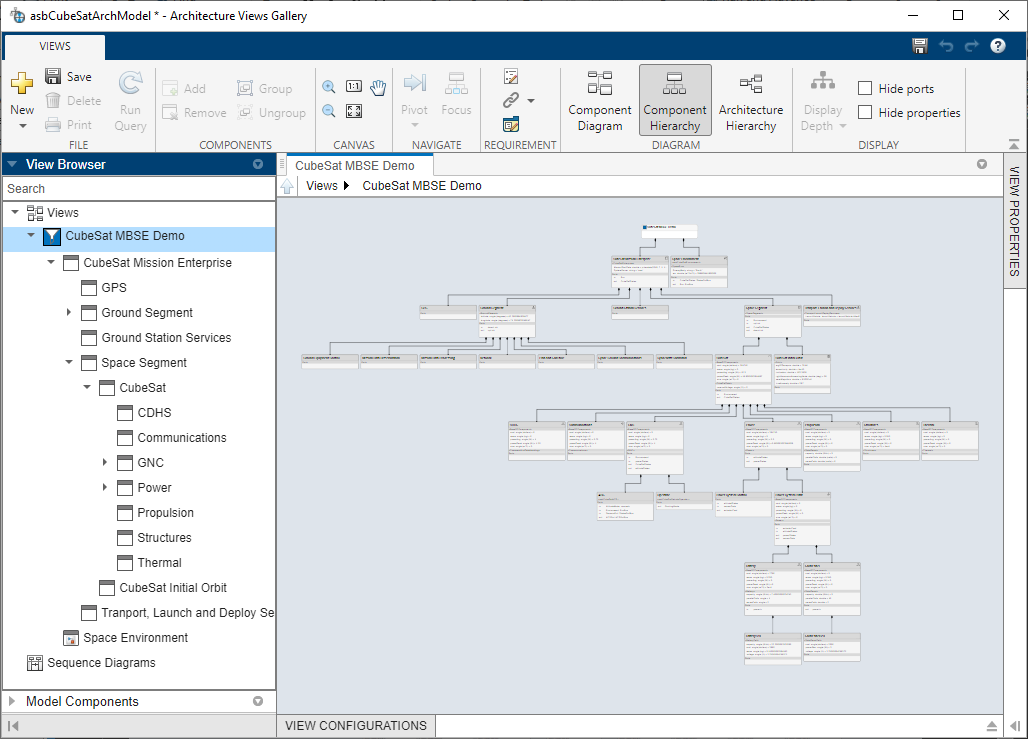

You can also view the hierarchy at different depths of the architecture.  For example, navigate to the `Power System Plant` component of the architecture by double-clicking the component in the **View Browser**.

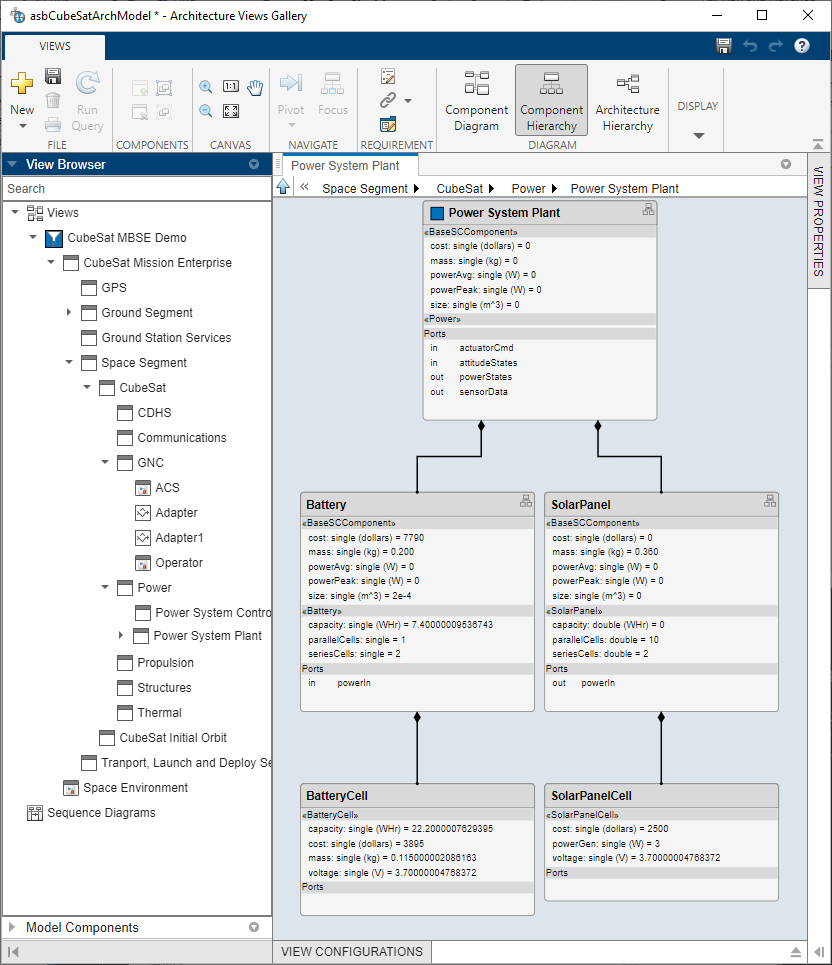

## Link Requirements to Architecture Components

To link requirements to the architecture elements that implement them, use the **Requirements Manager.** Drag the requirement onto the corresponding component, port, or interface. Using this linking mechanism, we are able to identify how requirements are met in the architectural model. The column labeled "Implemented" in the **Requirements Manager** shows whether a textual requirement has been linked to a component in the given model. For example, our top level requirement "Provide visual imagery" is linked to our top level component `CubeSat Mission Enterprise` with decomposed requirements linked to respective decomposed architectural components.

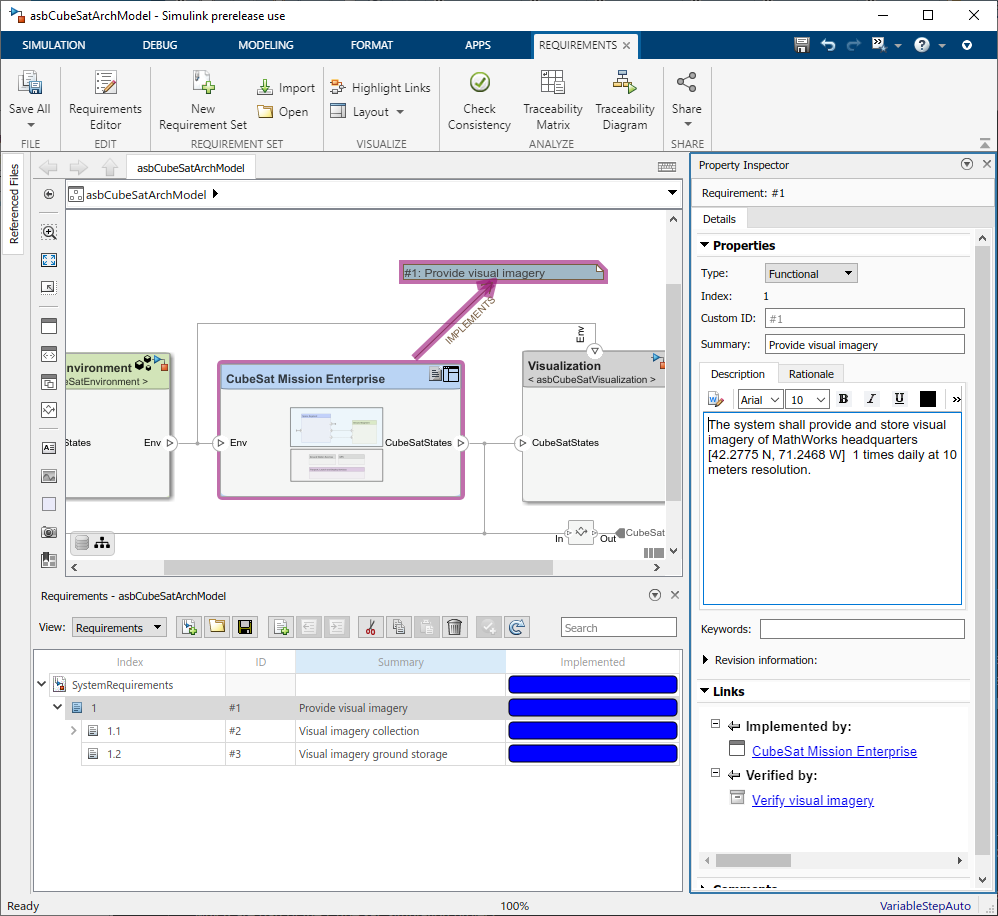

## Connecting the Architecture to Design Models

As the design process matures through analysis and other system engineering processes, we can begin to populate our architecture with dynamics models, and behavior models. System Composer is built as a layer on top of Simulink, which enables Simulink models to be directly referenced from the architectural components we have created. We can then simulate our architecture model as a Simulink model and generate results for analysis.  For example, the `GNC subsystem` component contains 3 Simulink model references that are part of the *CubeSat Simulation Project.*

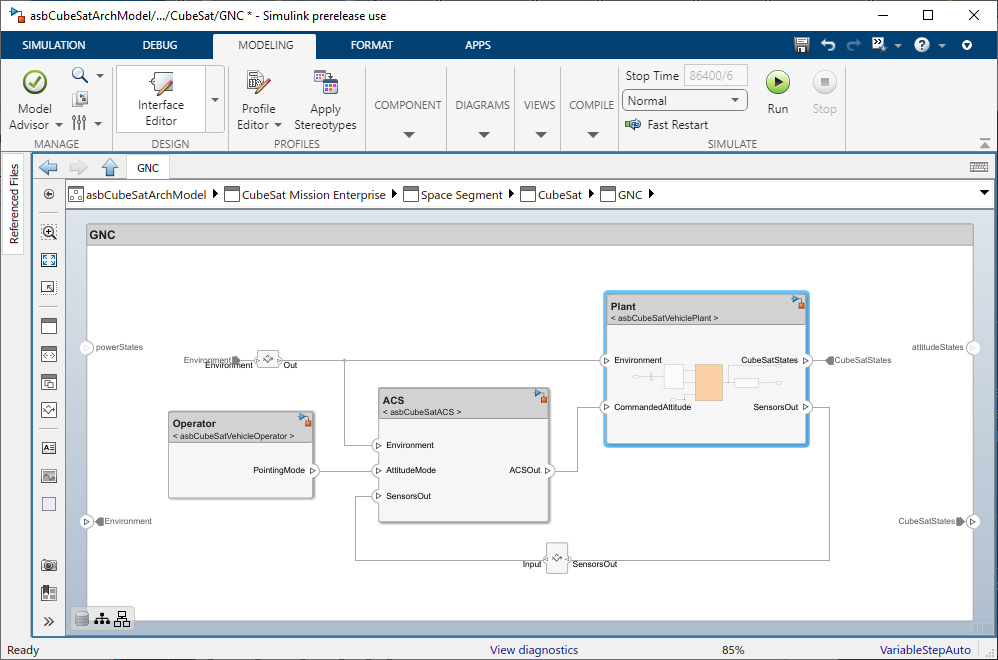

Double-click these reference components to open the the underlying Simulink models.  Notice that the interfaces defined in the architecture map to bus signals in the Simulink model.

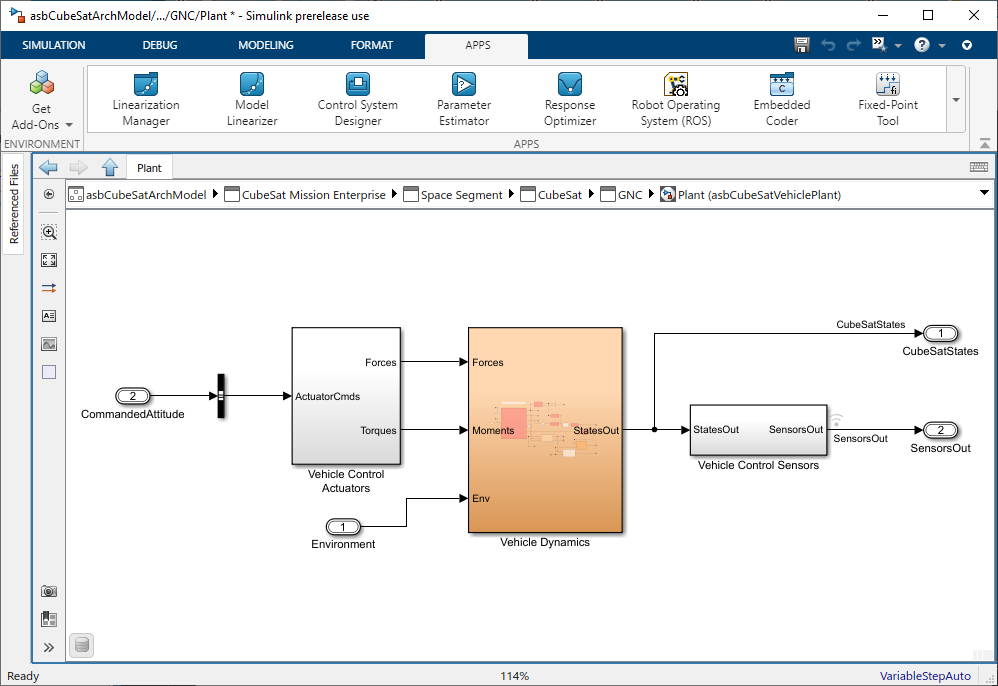

This example uses the **Spacecraft Dynamics** block from Aerospace Blockset to propagate the CubeSat orbit and rotational states.

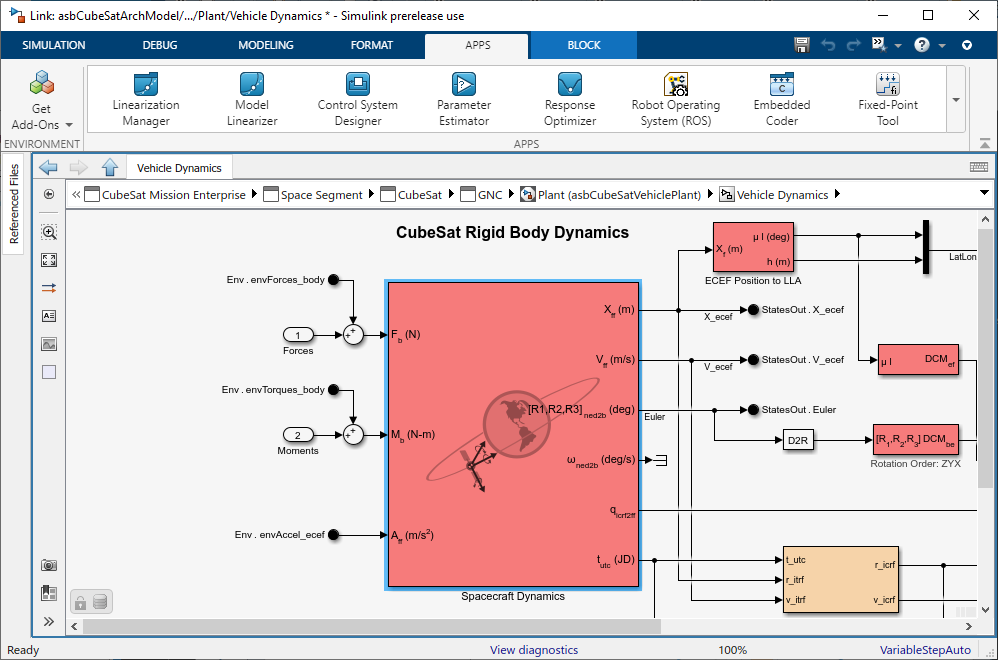

## Simulate System Architecture to Validate Orbital Requirements

We can use simulation to verify our system-level requirements. In this scenario, our top level requirement states that the CubeSat onboard camera captures an image of MathWorks Headquarters at [ 42.2775 N, 71.2468 W] once daily at 10 meters resolution. We can manually validate this requirement with various mission analysis tools.  For examples of these analyses, click on the project shortcuts *Analyze with Mapping Toolbox* and *Analyze with Satellite Scenario.*

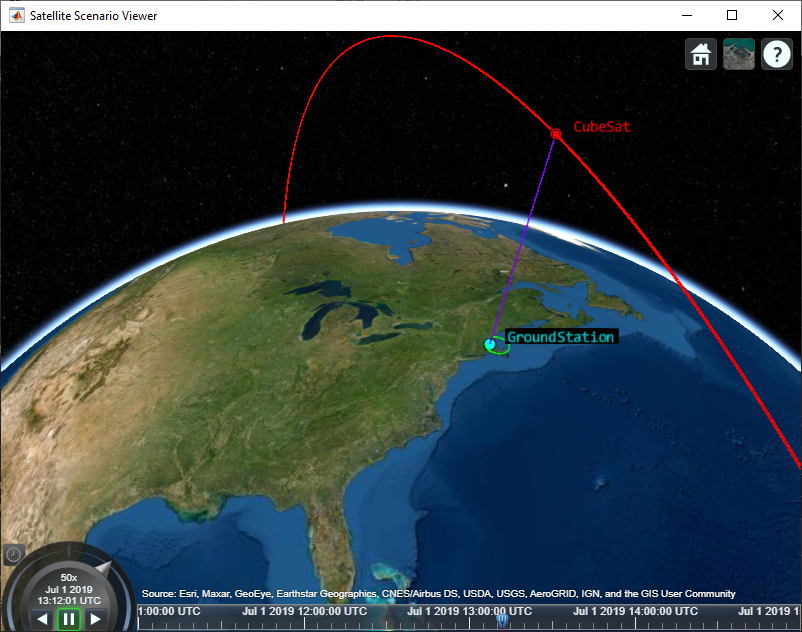

The satellite scenario created in the *Analyze with Satellite Scenario* shortcut example is shown above.

## Validate Orbital Requirements using Simulink Test

Although we can use MATLAB to visualize and analyze the CubeSat behavior, we can also use Simulink Test to build out test cases. This test case automates the requirements-based testing process by using the testing framework to test whether our CubeSat orbit and attitude meet our high-level requirement. The test case approach enables us to create a scalable, maintainable, and flexible testing infrastructure based on our textual requirements.

This example contains a test file *systemTests.mldatx. *Double click this file in the project folder browser to view it in the **Test Manager**. Our test file contains a test to verify our top-level requirement.  Our test point, "Verify visual imagery", is mapped to the requirement "Provide visual imagery" and defines a MATLAB function to use as custom criteria for the test.  While this test case is not a comprehensive validation of our overall mission, it is useful during early development to confirm our initial orbit selection is reasonable, allowing us to continue refining and adding detail to our architecture.

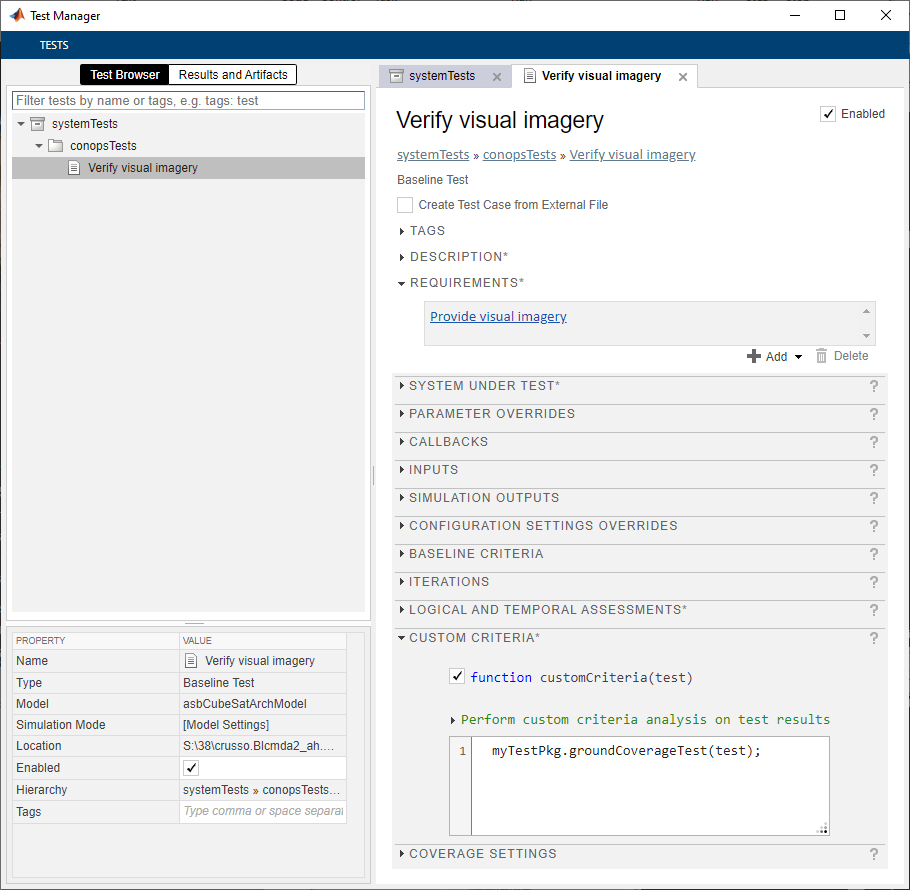

type("groundCoverageTest.m")

function groundCoverageTest(test)
% Custom verification function used by systemTests.mldatx to verify
% compliance with Requirement 1 - "Provide visual imagery"

%  Copyright 2021 The MathWorks, Inc.

    cubeSatModel = systemcomposer.loadModel("asbCubeSatArchModel");
    enterpriseComp = cubeSatModel.lookup("Path", ...
                                         "asbCubeSatArchModel/CubeSat Mission Enterprise");
    startDateJD = getEvaluatedPropertyValue(enterpriseComp, ...
                                            "CubeSatProfile.CubeSatEnterprise.MissionStartDate");
    startDate = datetime(startDateJD, ConvertFrom="juliandate");

    % Use satellite scenario access analysis to confirm sensor images
    % ground station at least once during simulation
    sc = satelliteScenario(startDate, startDate + hours(4), 60);

    % Add ground station to scenario
    gs = groundStation(sc, 42, -71, Name="GroundStation");

    % Add satellite from saved position data
    loggedPos = test.sltest

Run the test point in the **Test Manager **and confirm that the test passes. This confirms that the CubeSat onboard camera as visibility to the imaging target during the simulation window.  

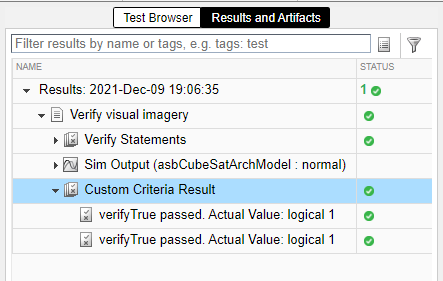 

## References

[1] “Space Systems Working Group.” INCOSE, 2019, https://www.incose.org/incose-member-resources/working-groups/Application/space-systems. 

*Copyright 2021 The MathWorks, Inc.*